# **Analisi preliminare**

## **Reset del workspace**

clear all %#ok<CLALL> 
clc

## Oggetti di configurazione

save_path = "..\..\Tesi\Immagini\4. Caso di studio\";
save_flag = false;

## Importazione dei dati

load('../Data/Processed data/Hourly_data.mat')
transport_ST = readtable('../Data/Sources/Train stations/Jersey_City_train_stations_data.csv');

## Processamento dei dati

### Variabili meteorologiche

weather_vars = {'X_beta_avg_feels_like_T', 'X_beta_rainfall', ...
    'X_beta_visibility', 'X_beta_windspeed', 'X_beta_cloud_cover'};
weather_names = ["Temperatura percepita [$^{\circ}$C]", "Pioggia [mm]", "Visibilit\'a [km]", ...
    "Velocit\'a del vento [km/h]", "Copertura nuvolosa [\%]"];
dates = unique(hourly_data.Time);
daily_weather_data = array2table(zeros(length(dates), length(weather_vars)));
daily_weather_data.Properties.VariableNames = weather_vars;
daily_weather_data.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), weather_vars);
    temp = temp(1, :);
    for j=1:length(weather_vars)
        if strcmp(weather_vars{j}, 'X_beta_rainfall')
            daily_weather_data{i, j} = sum(temp{1, weather_vars{j}}{1});
        else
            daily_weather_data{i, j} = mean(temp{1, weather_vars{j}}{1});
        end
    end
end

### Numero di ritiri

#### Per stazione (somma giornaliera)

n = size(unique(hourly_data(:, {'X_coordinate', 'Y_coordinate'})), 1);
daily_pickups_by_station = array2table(zeros(length(dates), n));
daily_pickups_by_station.Properties.VariableNames = arrayfun(@(x) ['S' num2str(x)], 1:n, 'UniformOutput', false);
daily_pickups_by_station.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), 'Y');
    for j=1:n
        daily_pickups_by_station{i, j} = sum(temp{j, 1}{:});
    end
end

#### Per ora (media sulle stazioni)

daily_mean_pickups_by_hour = array2table(zeros(length(dates), 24));
daily_mean_pickups_by_hour.Properties.VariableNames = arrayfun(@(x) ['H' num2str(x)], 0:23, 'UniformOutput', false);
daily_mean_pickups_by_hour.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), 'Y');
    means = mean(cell2mat(table2cell(temp)), 1);
    for j=1:24
        daily_mean_pickups_by_hour{i, j} = means(j);
    end
end

### Variabili dummy

dummy_vars = {'X_beta_holidays', 'X_beta_lockdown', 'X_beta_happy'};
days_info = array2table(zeros(length(dates), length(dummy_vars)));
days_info.Properties.VariableNames = dummy_vars;
days_info.Time = dates;
for i=1:length(dates)
    temp = hourly_data(hourly_data.Time == dates(i), dummy_vars);
    temp = temp(1, :);
    for j=1:length(dummy_vars)
        if max(temp{1, dummy_vars{j}}{1}) == 1
            days_info{i, j} = true;
        else
            days_info{i, j} = false;
        end
    end
end

### Variabili spaziali

spatial_vars = {'X_beta_ts_distance', 'X_beta_dem'};
spatial_data = array2table(zeros(n, length(spatial_vars)));
spatial_data.Properties.VariableNames = spatial_vars;
spatial_data = horzcat(spatial_data, hourly_data(1:n, {'X_coordinate', 'Y_coordinate'}));
for i=1:n
    for j=1:length(spatial_vars)
        spatial_data{i, j} = hourly_data{i, spatial_vars{j}}{:}(1);
    end
end

## Mappe

### Punti di ritiro e stazioni del treno

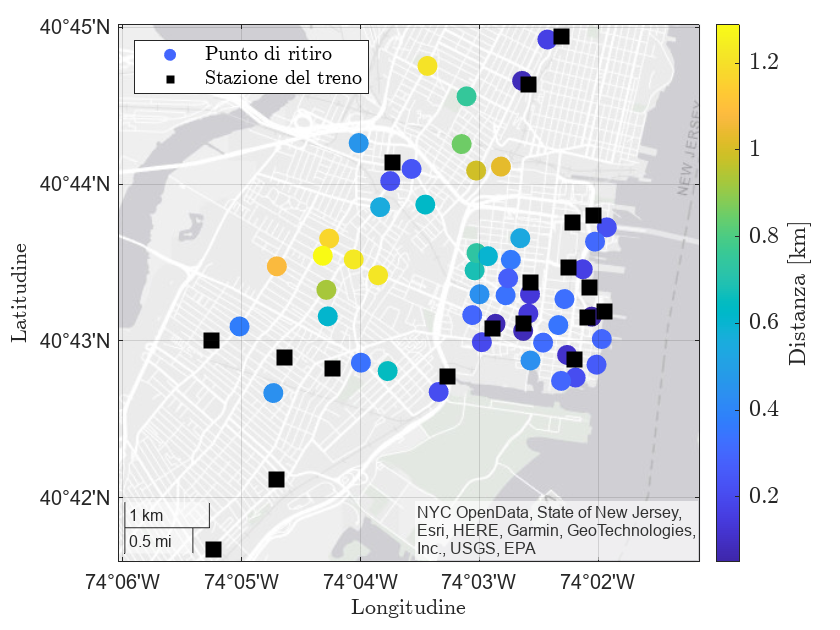

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
s = geoscatter(spatial_data, "Y_coordinate", "X_coordinate", "filled");
s.ColorVariable = "X_beta_ts_distance";
s.SizeData = 100;
gx = s.Parent;
gx.LatitudeLabel.String = "Latitudine";
gx.LatitudeLabel.Interpreter = "latex";
gx.LongitudeLabel.String = "Longitudine";
gx.LongitudeLabel.Interpreter = "latex";
c = colorbar;
c.Label.String = "Distanza [km]";
c.Label.Interpreter = "latex";
c.FontSize = 12;
c.TickLabelInterpreter = "latex";

hold on
g = geoscatter(transport_ST, "Lat", "Lon", "filled", "Marker", "square",...
    "MarkerFaceColor", "k");
g.SizeData = 100;
legend("Punto di ritiro", "Stazione del treno", "FontSize", 10,...
    "Interpreter", "latex", 'Location', 'northwest')


if save_flag
    file_name = "Mappe\Mappa punti ritiro e stazioni treno.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

### Densità abitativa

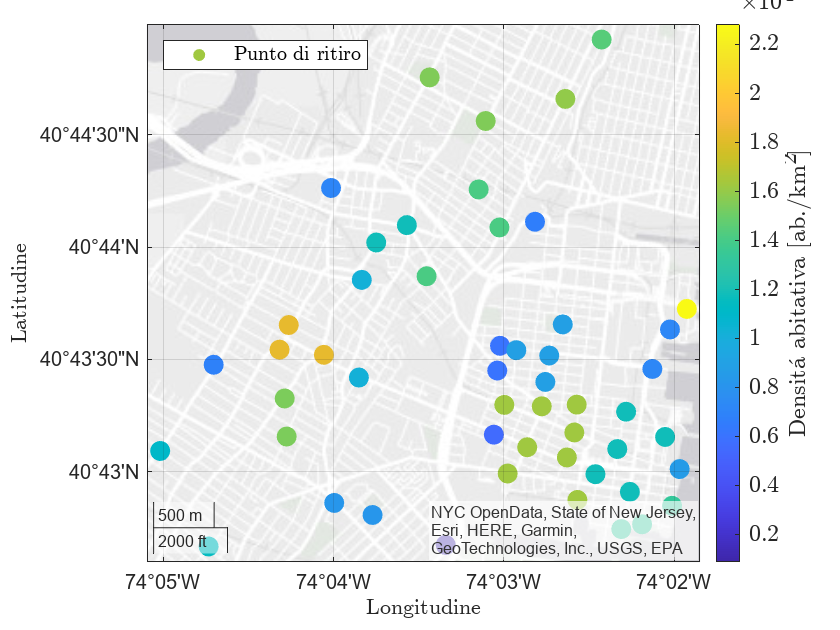

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
s = geoscatter(spatial_data, "Y_coordinate", "X_coordinate", "filled");
s.ColorVariable = "X_beta_dem";
s.SizeData = 100;
gx = s.Parent;
gx.LatitudeLabel.String = "Latitudine";
gx.LatitudeLabel.Interpreter = "latex";
gx.LongitudeLabel.String = "Longitudine";
gx.LongitudeLabel.Interpreter = "latex";
c = colorbar;
c.Label.String = "Densit\'a abitativa [ab./km$^2$]";
c.Label.Interpreter = "latex";
c.FontSize = 12;
c.TickLabelInterpreter = "latex";
legend("Punto di ritiro", "FontSize", 10,...
    "Interpreter", "latex", 'Location', 'northwest')


if save_flag
    file_name = "Mappe\Mappa punti ritiro e densità abitativa.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

### Numero medio di ritiri giornaliero

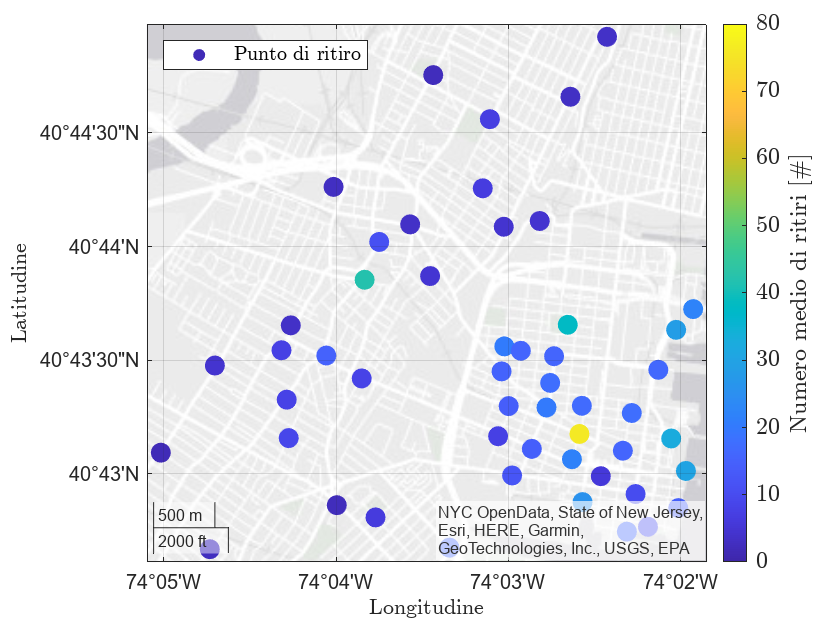

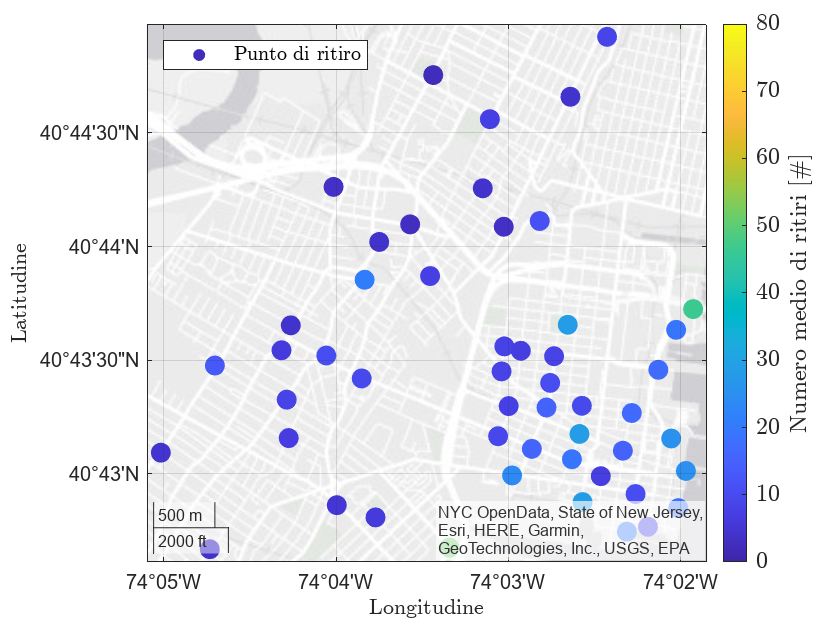

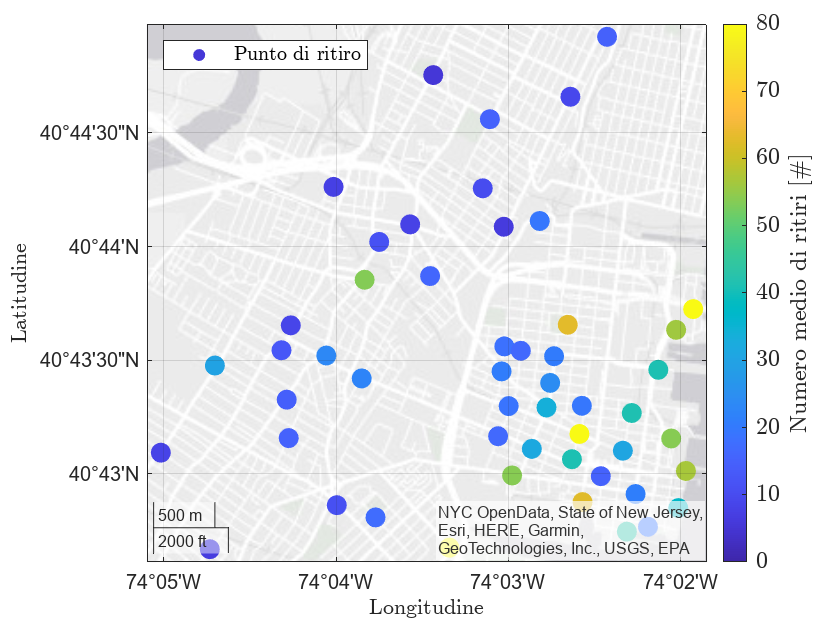

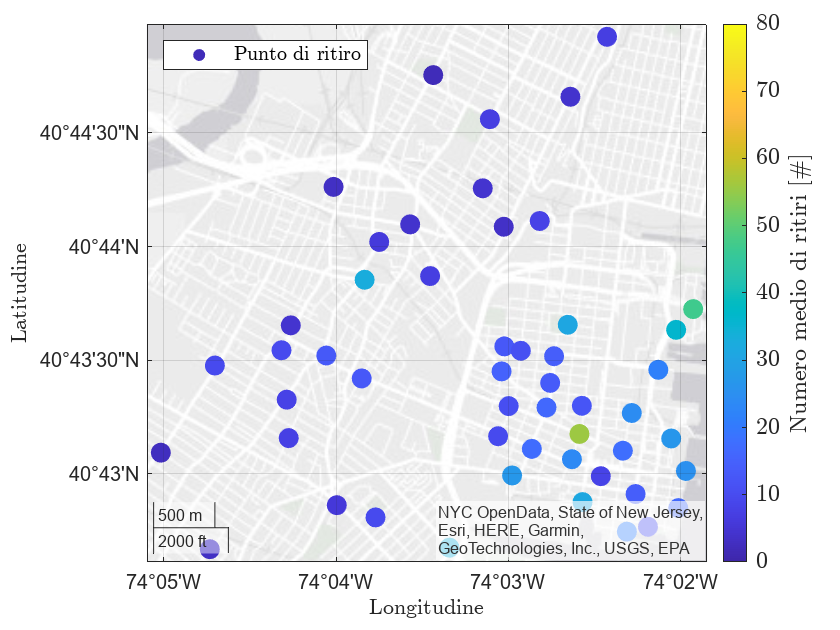

mean_daily_pickups_by_station = table();
mean_daily_pickups_by_station.X_coordinate = spatial_data.X_coordinate;
mean_daily_pickups_by_station.Y_coordinate = spatial_data.Y_coordinate;
mean_daily_pickups_by_station.Mean_daily_pickups = transpose(mean(daily_pickups_by_station{:, 1:end-1}));

spring_filter = dates >= datetime(2020, 3, 20) & dates <= datetime(2020, 6, 20);
summer_filter = dates >= datetime(2020, 6, 21) & dates <= datetime(2020, 9, 22);
autumn_filter = dates >= datetime(2020, 9, 23) & dates <= datetime(2020, 12, 20);
winter_filter = ~(spring_filter | summer_filter | autumn_filter);
season_filters = [winter_filter, spring_filter, summer_filter, autumn_filter];

nomi_stagioni = ["inverno", "primavera", "estate", "autunno"];
for i=1:4
    figure
    t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    nexttile
    mean_daily_pickups_by_station.Mean_daily_pickups = transpose(mean(daily_pickups_by_station{season_filters(:, i), ...
        1:end-1}));
    s = geoscatter(mean_daily_pickups_by_station, "Y_coordinate", "X_coordinate", "filled");
    s.ColorVariable = "Mean_daily_pickups";
    s.SizeData = 100;
    gx = s.Parent;
    gx.LatitudeLabel.String = "Latitudine";
    gx.LatitudeLabel.Interpreter = "latex";
    gx.LongitudeLabel.String = "Longitudine";
    gx.LongitudeLabel.Interpreter = "latex";
    c = colorbar;
    clim([0, 80])
    c.Label.String = "Numero medio di ritiri [\#]";
    c.Label.Interpreter = "latex";
    c.FontSize = 12;
    c.TickLabelInterpreter = "latex";
    legend("Punto di ritiro", "FontSize", 10,...
        "Interpreter", "latex", 'Location', 'northwest')

    if save_flag
        file_name = "Mappe\Mappa ritiri, " + nomi_stagioni(i) + ".pdf";
        exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
    end
end

## Analisi delle variabili meteorologiche

### Istogrammi

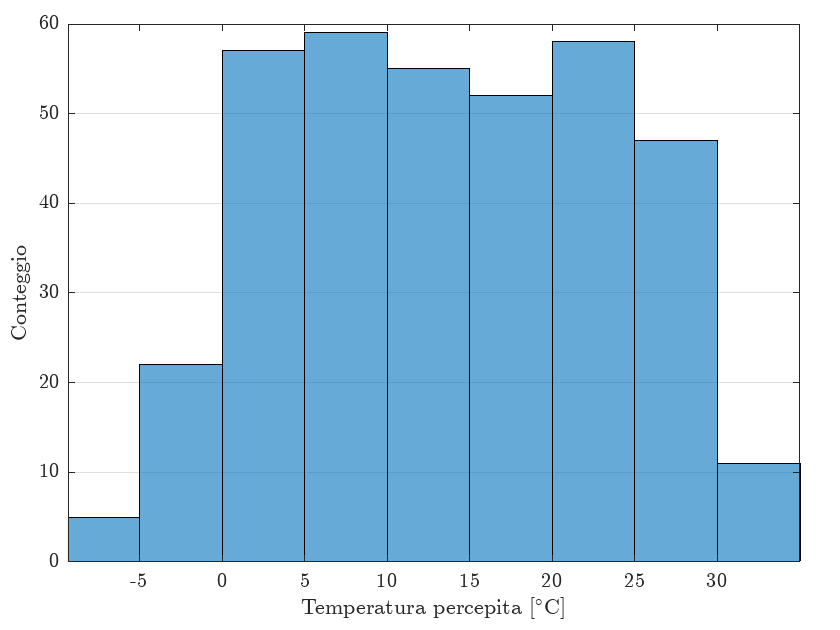

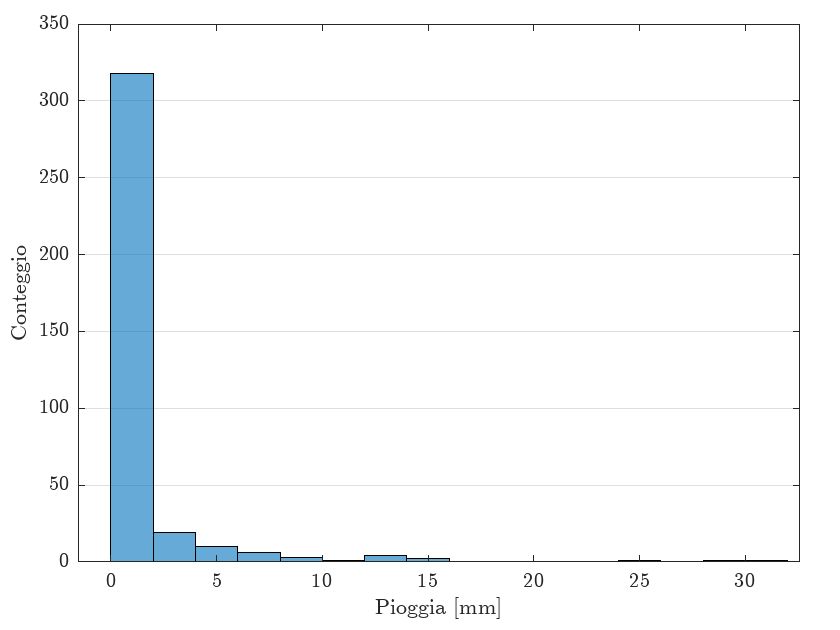

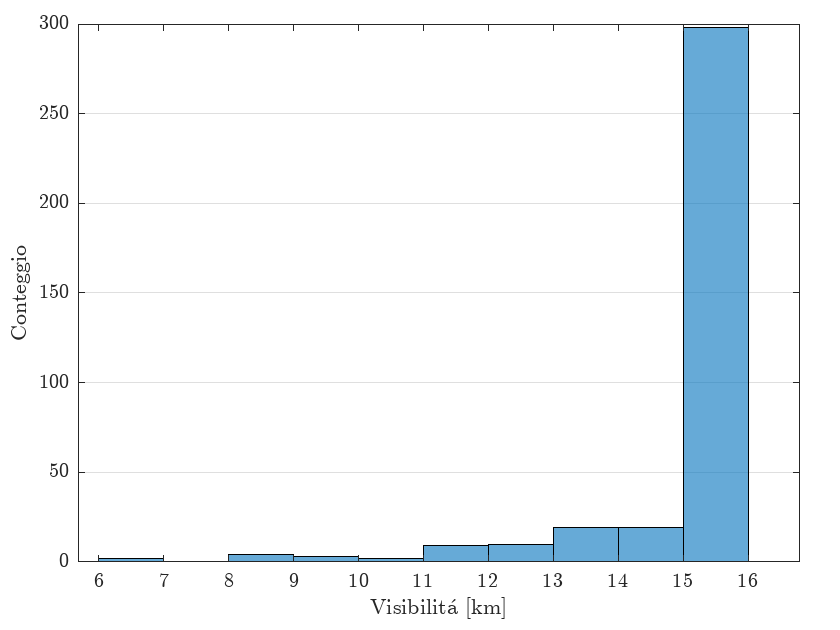

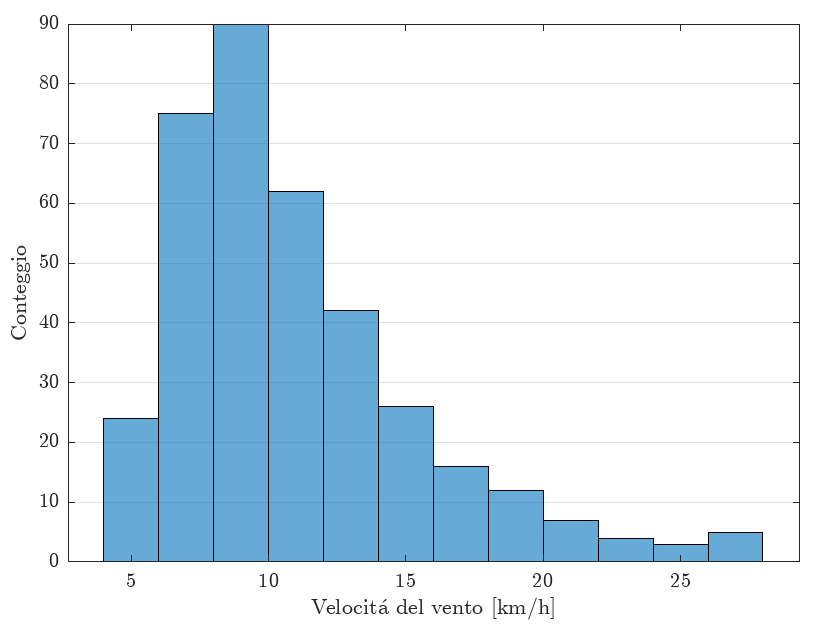

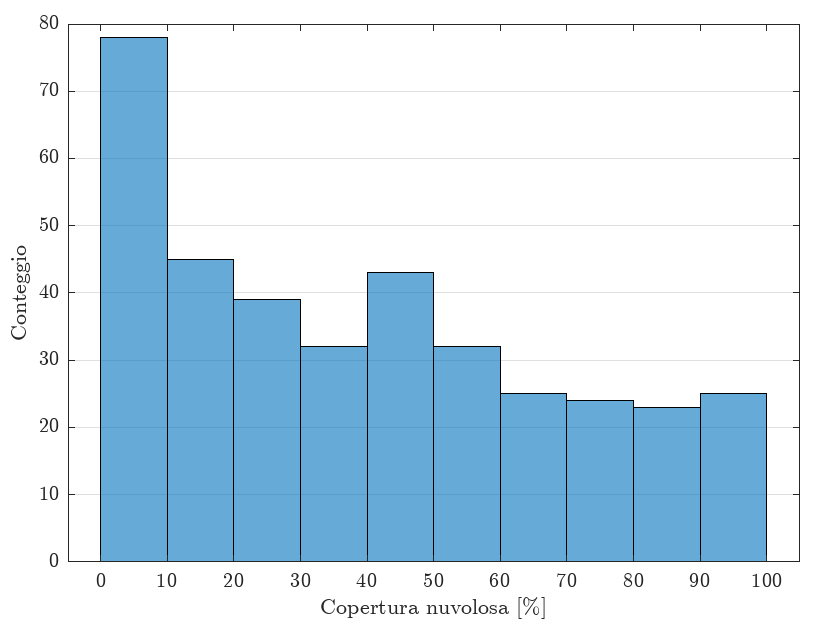

nomi_variabili_meteo = ["temperatura percepita", "pioggia", "visibilità", ...
    "velocità vento", "copertura nuvolosa"];
for i=1:length(weather_vars)
    figure
    t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    nexttile
    histogram(daily_weather_data{:, i}, 'Orientation', 'vertical', 'FaceColor', '#0072BD')
    xlim([min(daily_weather_data{:, i})-.05*max(daily_weather_data{:, i}), ...
        max(daily_weather_data{:, i})+.05*max(daily_weather_data{:, i})]);
    axs = gca;
    axs.XAxis.TickLabelInterpreter = 'latex';
    xlabel(weather_names(i), 'Interpreter', 'latex');
    axs.YAxis.TickLabelInterpreter = 'latex';
    ylabel('Conteggio', 'Interpreter', 'latex');
    axs.YGrid = 'on';

    if save_flag
        file_name = "Istogrammi\Istogramma, " + nomi_variabili_meteo(i) + ".pdf";
        exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
    end
end

### Box-plot

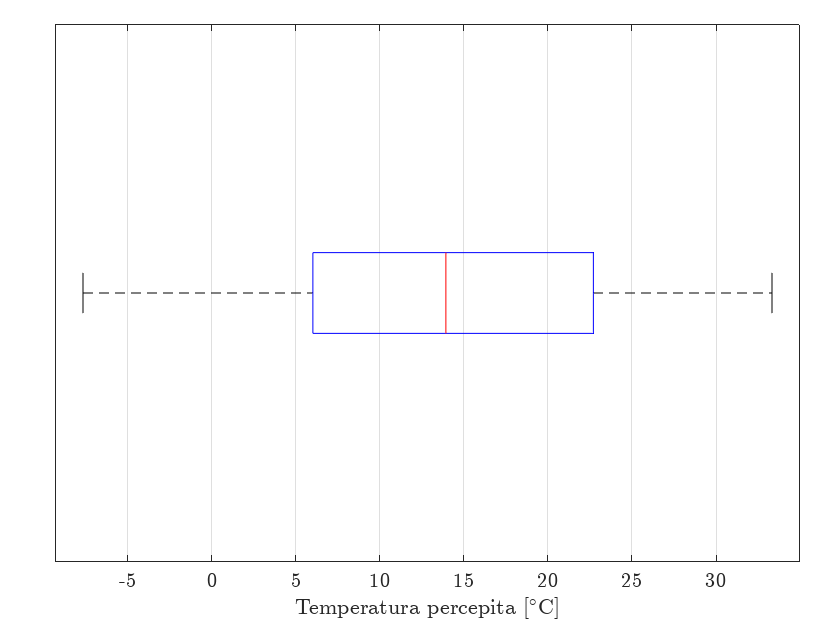

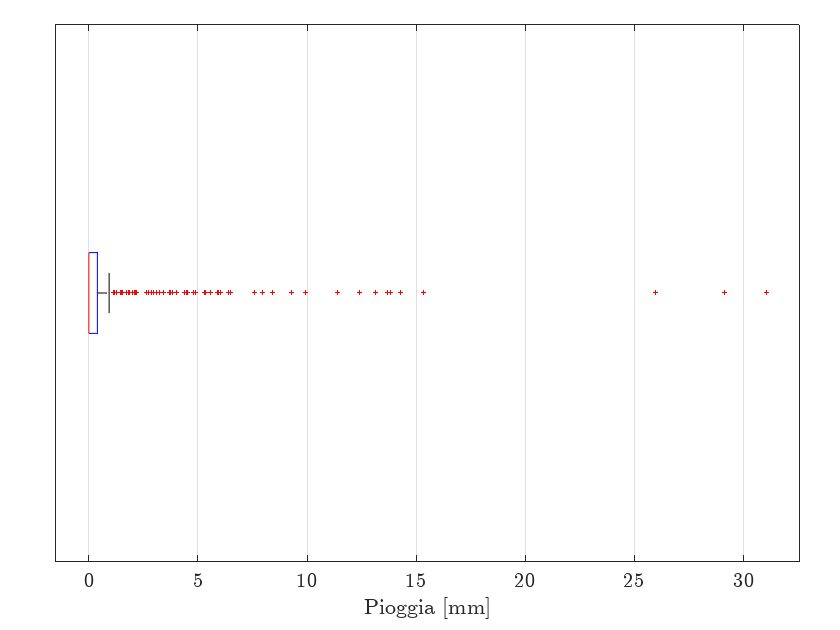

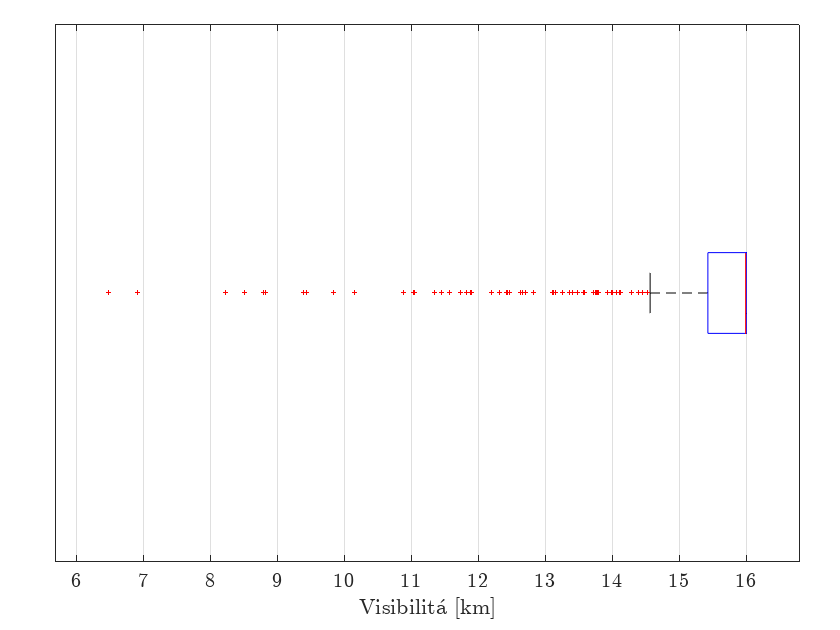

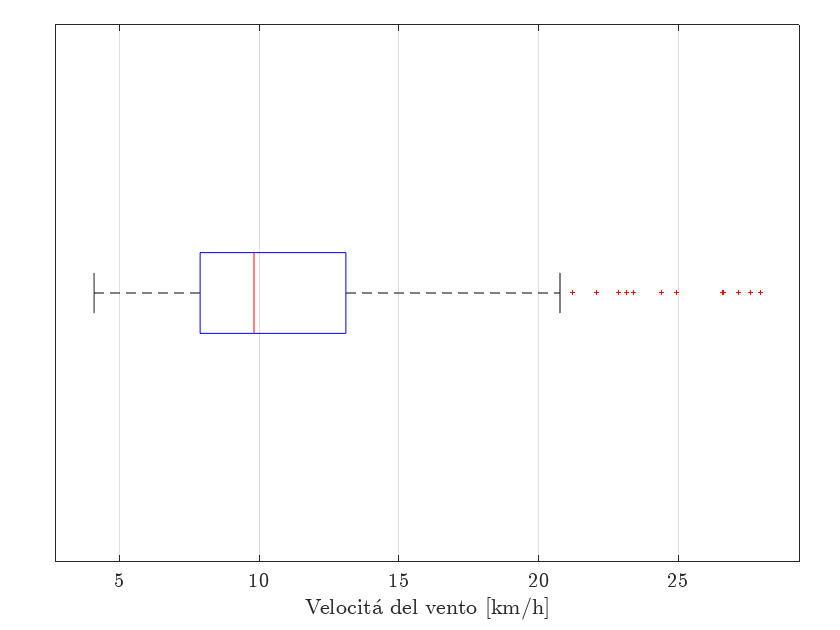

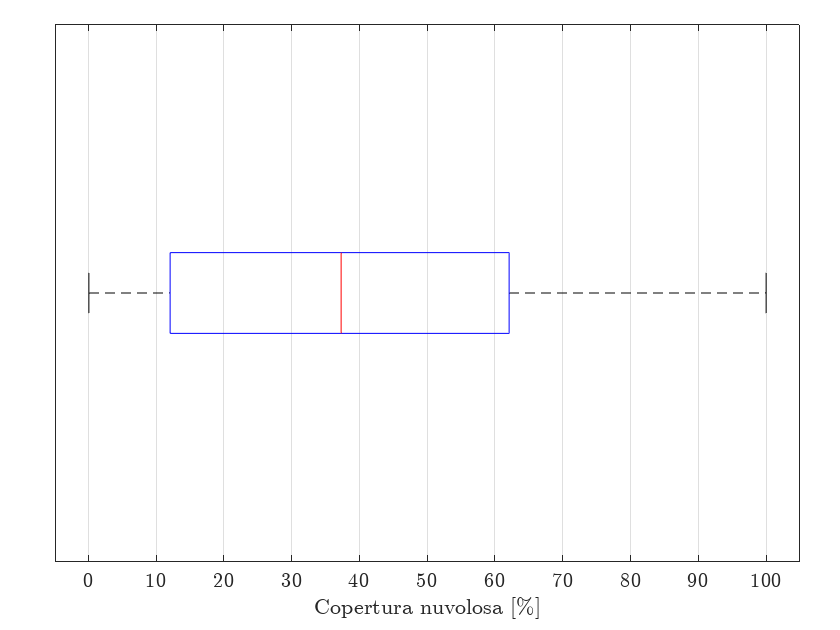

for i=1:length(weather_vars)
    figure
    t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    nexttile
    boxplot(daily_weather_data{:, i}, 'Orientation', 'horizontal', 'OutlierSize', 1.5)
    xlim([min(daily_weather_data{:, i})-.05*max(daily_weather_data{:, i}), ...
        max(daily_weather_data{:, i})+.05*max(daily_weather_data{:, i})]);
    axs = gca;
    axs.XAxis.TickLabelInterpreter = 'latex';
    axs.YAxis.TickValues = '';
    xlabel(weather_names(i), 'Interpreter', 'latex')
    axs.YAxis.TickLabelInterpreter = 'latex';
    axs.XGrid = 'on';

    if save_flag
        file_name = "Box-plot\Box-plot, " + nomi_variabili_meteo(i) + ".pdf";
        exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
    end
end

## Visualizzazione e confronto tra serie storiche

### Numero di ritiri

#### Media giornaliera

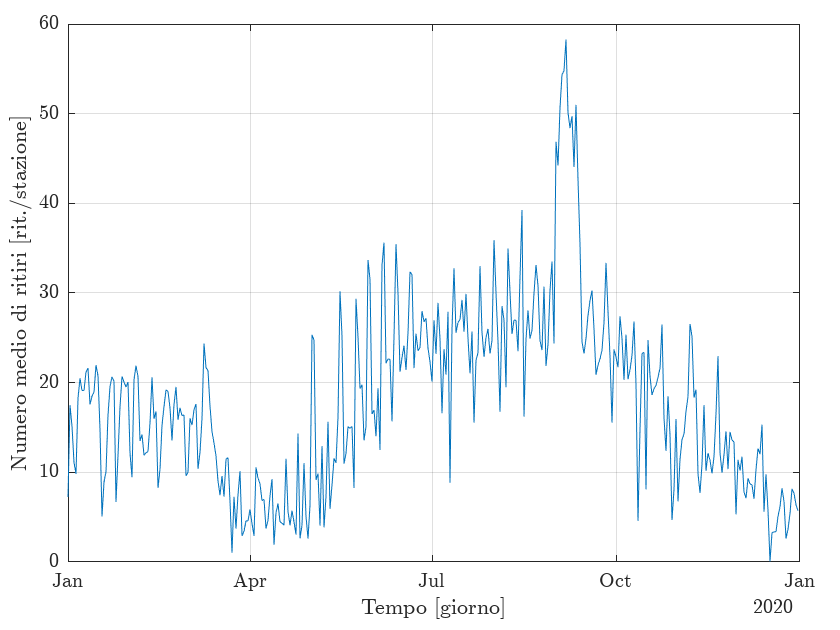

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
plot(daily_weather_data.Time, mean(daily_pickups_by_station{:, 1:end-1}, 2))
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Tempo [giorno]", 'Interpreter', 'latex')
axs.XGrid = 'on';
axs.YAxis.TickLabelInterpreter = 'latex';
ylabel("Numero medio di ritiri [rit./stazione]", 'Interpreter', 'latex')
axs.YGrid = 'on';


if save_flag
    file_name = "Serie storiche\Ritiri giornalieri.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

#### Media oraria (per stagione)

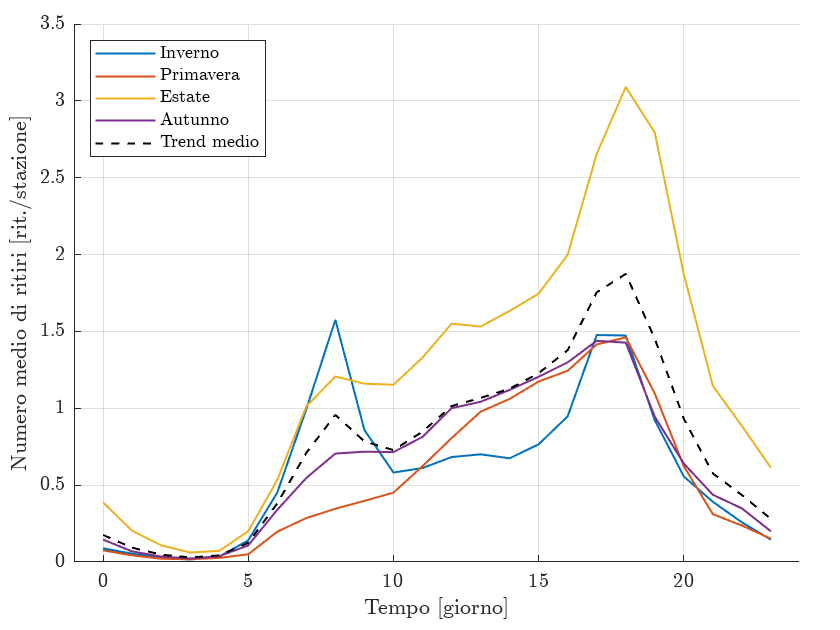

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
hold on
for i=1:4
    plot(0:1:23, mean(daily_mean_pickups_by_hour{season_filters(:, i), 1:end-1}, 1), ...
        'LineWidth', 1)
end
plot(0:1:23, mean(daily_mean_pickups_by_hour{:, 1:end-1}, 1), ...
        'LineWidth', 1, 'LineStyle', '--', 'Color', 'black')
hold off
xlim([-1 24])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Tempo [giorno]", 'Interpreter', 'latex')
axs.XGrid = 'on';
axs.YAxis.TickLabelInterpreter = 'latex';
ylabel("Numero medio di ritiri [rit./stazione]", 'Interpreter', 'latex')
axs.YGrid = 'on';
legend("Inverno", "Primavera", "Estate", "Autunno", "Trend medio", 'Interpreter', 'latex', ...
    'Location', 'northwest')


if save_flag
    file_name = "Serie storiche\Ritiri orari.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

#### Media oraria (per tipologia di giorno)

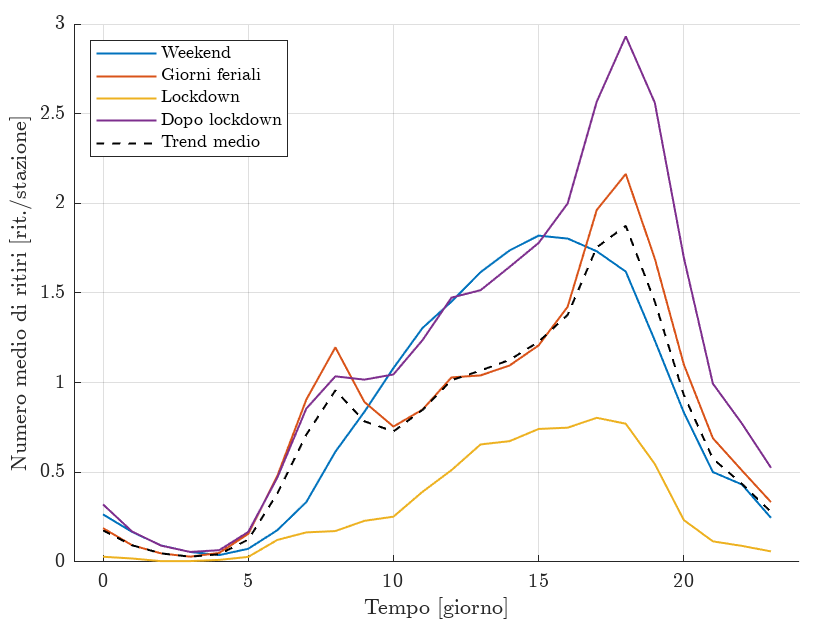

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
hold on
plot(0:1:23, mean(daily_mean_pickups_by_hour{logical(days_info.X_beta_holidays) & ~logical(days_info.X_beta_lockdown), ...
    1:end-1}, 1), 'LineWidth', 1)
plot(0:1:23, mean(daily_mean_pickups_by_hour{~logical(days_info.X_beta_holidays) & ~logical(days_info.X_beta_lockdown), ...
    1:end-1}, 1), 'LineWidth', 1)
plot(0:1:23, mean(daily_mean_pickups_by_hour{logical(days_info.X_beta_lockdown), 1:end-1}, 1), ...
        'LineWidth', 1)
plot(0:1:23, mean(daily_mean_pickups_by_hour{logical(days_info.X_beta_happy), 1:end-1}, 1), ...
        'LineWidth', 1)
plot(0:1:23, mean(daily_mean_pickups_by_hour{:, 1:end-1}, 1), ...
        'LineWidth', 1, 'LineStyle', '--', 'Color', 'black')
hold off
xlim([-1 24])
axs = gca;
axs.XAxis.TickLabelInterpreter = 'latex';
xlabel("Tempo [giorno]", 'Interpreter', 'latex')
axs.XGrid = 'on';
axs.YAxis.TickLabelInterpreter = 'latex';
ylabel("Numero medio di ritiri [rit./stazione]", 'Interpreter', 'latex')
axs.YGrid = 'on';
legend("Weekend", "Giorni feriali", "Lockdown", "Dopo lockdown", "Trend medio", 'Interpreter', 'latex', ...
    'Location', 'northwest')

if save_flag
    file_name = "Serie storiche\Ritiri orari, tipologia di giorno.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

### Numero di ritiri e variabili esplicative

#### Variabili meteorologiche

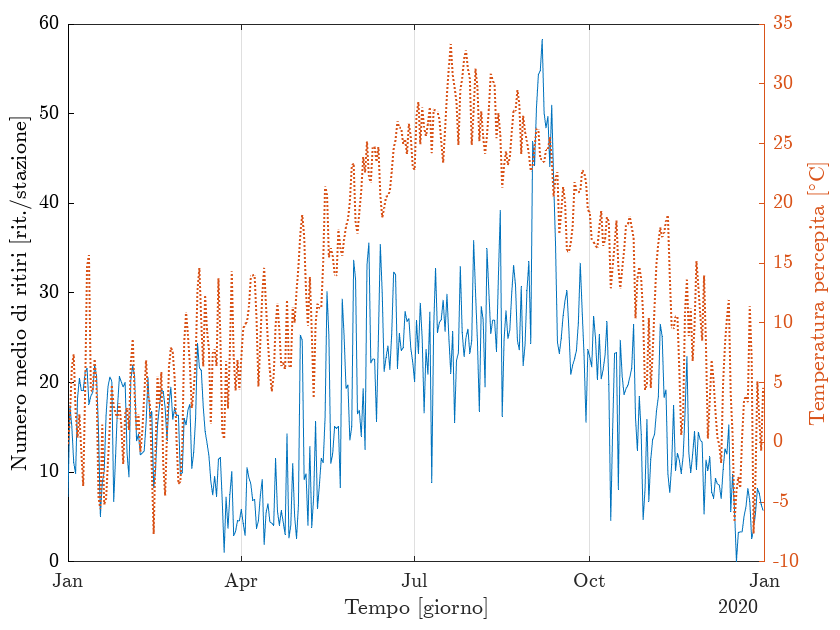

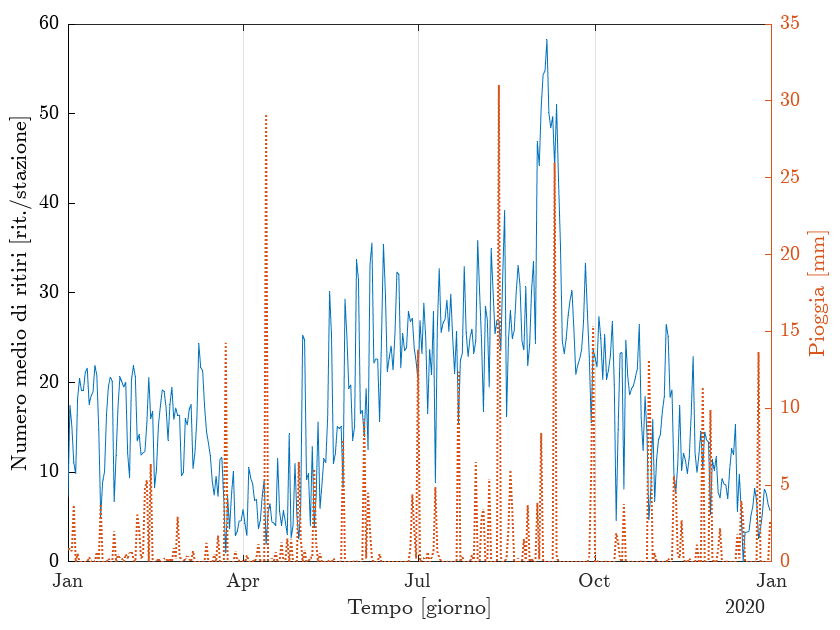

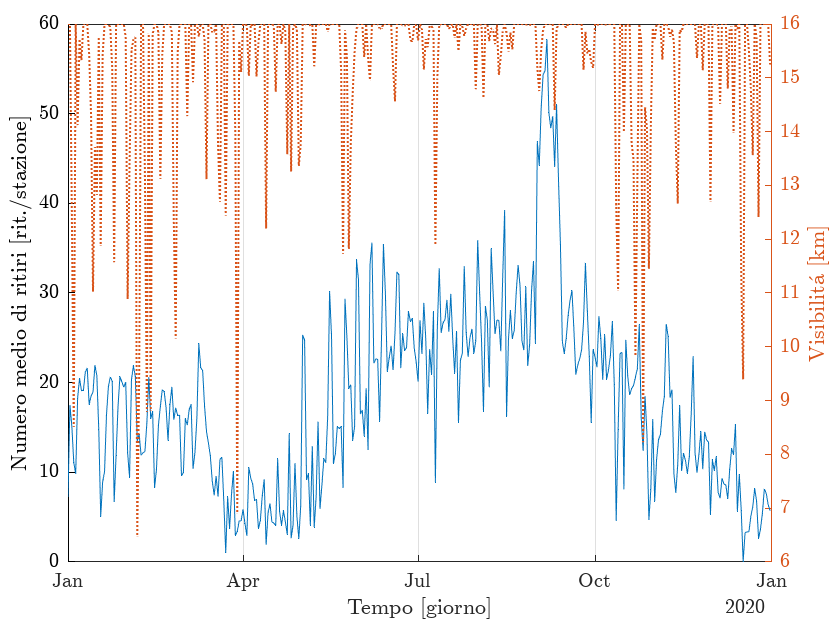

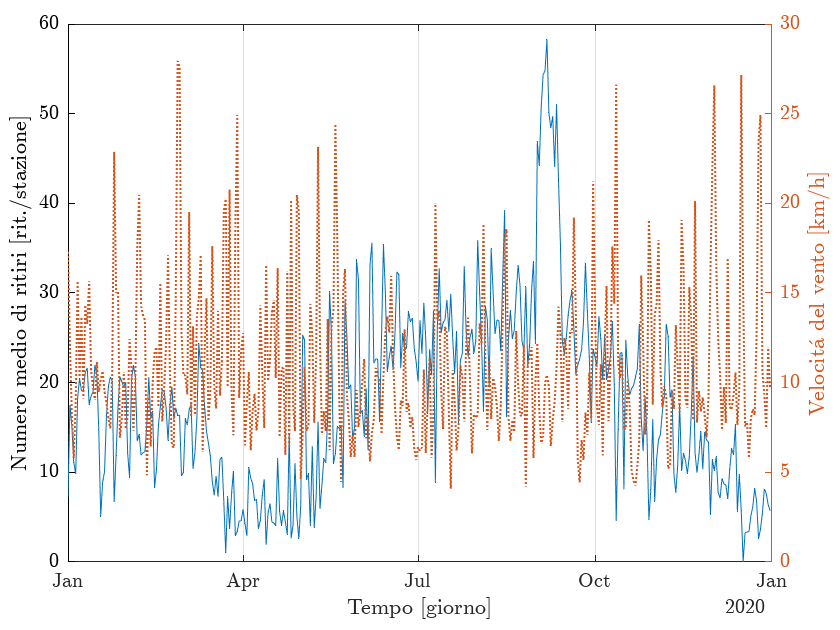

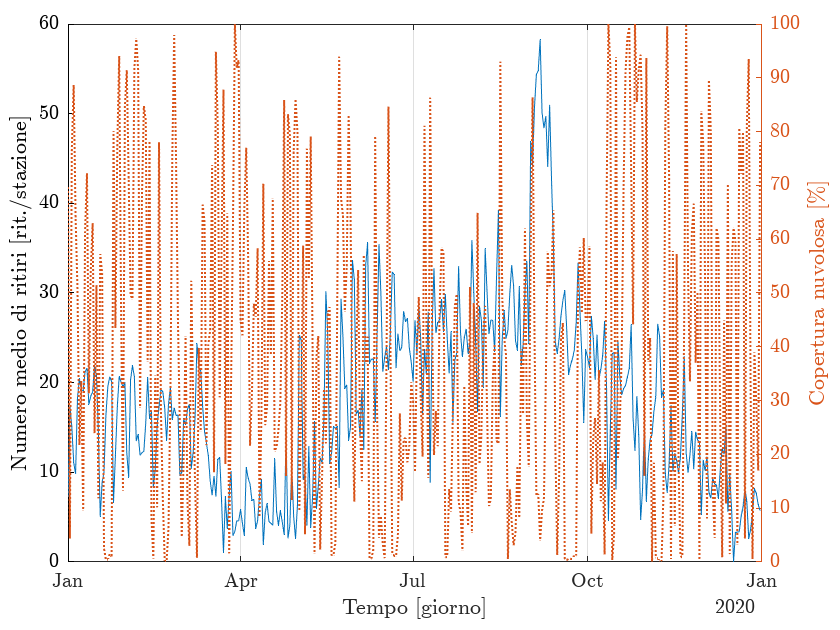

for i = 1:length(weather_vars)
    figure
    t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    nexttile
    plot(daily_weather_data.Time, mean(daily_pickups_by_station{:, 1:end-1}, 2))
    alpha(0.1);
    axs = gca;
    axs.XAxis.TickLabelInterpreter = 'latex';
    xlabel("Tempo [giorno]", 'Interpreter', 'latex')
    axs.XGrid = 'on';
    axs.YAxis.TickLabelInterpreter = 'latex';
    ylabel('Numero medio di ritiri [rit./stazione]', 'Interpreter', 'latex')
    hold on
    yyaxis right
    plot(daily_weather_data.Time, daily_weather_data{:, i}, 'LineStyle', ':', 'LineWidth', 1)
    axs = gca;
    axs.YAxis(2,1).TickLabelInterpreter = 'latex';
    ylabel(weather_names(i), 'Interpreter', 'latex')

    if save_flag
        file_name = "Serie storiche\Ritiri giornalieri e " +  nomi_variabili_meteo(i) + ".pdf";
        exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
    end
end

#### Variabili dummy

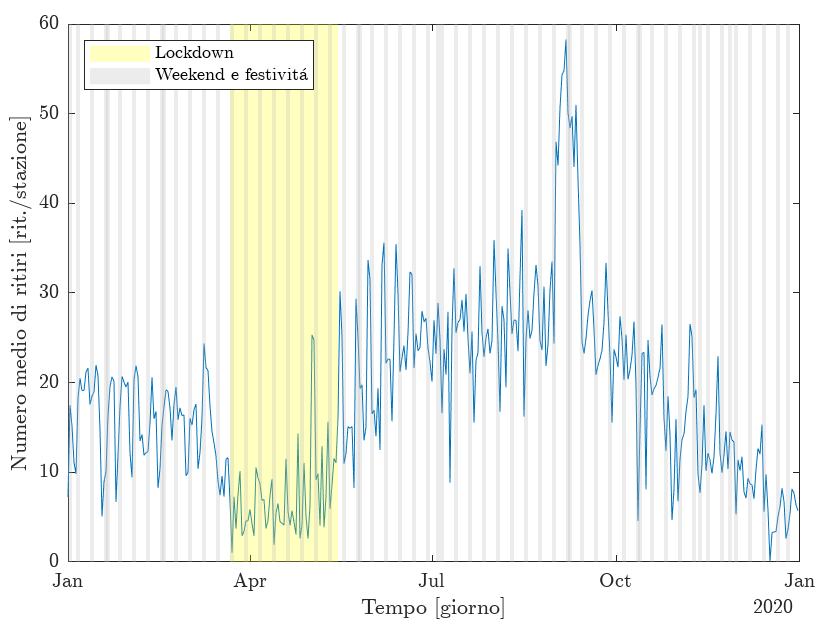

figure
t = tiledlayout(1, 1, 'TileSpacing', 'Compact', 'Padding', 'Compact');
nexttile
plot(daily_weather_data.Time, mean(daily_pickups_by_station{:, 1:end-1}, 2))
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
xlabel("Tempo [giorno]", 'Interpreter', 'latex')
axs = gca;
axs.YAxis.TickLabelInterpreter = 'latex';
ylabel('Numero medio di ritiri [rit./stazione]', 'Interpreter', 'latex')
v = [81 0; 135 0; 135 60; 81 60];
f = [1 2 3 4];
patch('Faces', f, 'Vertices', v, 'EdgeColor', 'none', ...
    'FaceColor', [1 1 0], 'FaceAlpha',.25)
holidays = find(days_info.X_beta_holidays == 1);
c = 1;
for i = 1:1:360
    if i == holidays(c)
        c = c+1;
        vi = [i-1 0; i+1 0; i+1 60; i-1 60];
        patch('Faces', f, 'Vertices', vi, 'EdgeColor', 'none',...
            'FaceColor', [.7 .7 .7], 'FaceAlpha', .25)
    end
end
legend("", "Lockdown", "Weekend e festivit\'a", 'Interpreter', 'latex', 'Location', 'northwest')

if save_flag
    file_name = "Serie storiche\Ritiri giornalieri e dummy.pdf";
    exportgraphics(t, save_path + file_name, 'BackgroundColor', 'none');
end

## Tabelle

### Variabili meteorologiche

weather_summary = table();
weather_summary.Var = transpose(weather_vars);
weather_summary.Min = round(transpose(min(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Mean = round(transpose(mean(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Median = round(transpose(median(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Max = round(transpose(max(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Std = round(transpose(std(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Skw = round(transpose(skewness(daily_weather_data{:, 1:end-1})), 2);
weather_summary.Kurt = round(transpose(kurtosis(daily_weather_data{:, 1:end-1})), 2);

### Variabili spaziali

spatial_summary = table();
spatial_summary.Var = transpose(spatial_vars);
spatial_summary.Min = round(transpose(min(spatial_data{:, 1:end-2})), 2);
spatial_summary.Mean = round(transpose(mean(spatial_data{:, 1:end-2})), 2);
spatial_summary.Median = round(transpose(median(spatial_data{:, 1:end-2})), 2);
spatial_summary.Max = round(transpose(max(spatial_data{:, 1:end-2})), 2);
spatial_summary.Std = round(transpose(std(spatial_data{:, 1:end-2})), 2);
spatial_summary.Skw = round(transpose(skewness(spatial_data{:, 1:end-2})), 2);
spatial_summary.Kurt = round(transpose(kurtosis(spatial_data{:, 1:end-2})), 2);

### Distanze medie tra i punti di ritiro

dist_mat = zeros(size(spatial_data, 1));
for i=1:size(spatial_data, 1)
    for j=1:size(spatial_data, 1)
        if i~=j
            dist_mat(i, j) = distance(spatial_data.Y_coordinate(i), spatial_data.X_coordinate(i), ...
                spatial_data.Y_coordinate(j), spatial_data.X_coordinate(j), ...
                wgs84Ellipsoid('km'));
        end
    end
end

k = 2;
k_min_distances = zeros(size(spatial_data, 1), k);
for i=1:size(spatial_data, 1)
    temp = sort(dist_mat(i, :));
    k_min_distances(i, :) = temp(2:1:2+k-1);
end
std(mean(k_min_distances, 2))

ans = 0.1892